1

p = @(x) x.^5-10*x.^3+21*x;
pp= [1 0 -10 0 21 0]

pp =      1     0   -10     0    21     0


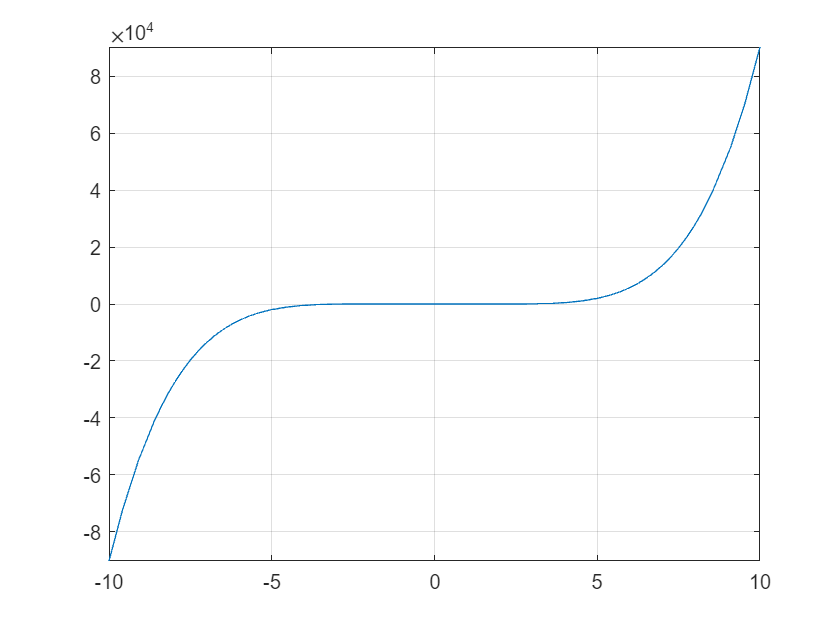

fplot(p,[-10,10])
grid on

root_num1 = roots(pp)

root_num1 =                    0
  -2.645751311064594
  -1.732050807568875
   2.645751311064589
   1.732050807568877


3

p(0)

ans =      0


p(-2.6458)

ans =   -0.002726831271893


p(-1.7321)

ans =    0.001180618344563


4.

f = @(x) exp(x).*cos(x).^2-2

f = function_handle with value:
    @(x)exp(x).*cos(x).^2-2


fplot(f,[0,5])
ylim([-5,10])
h=0.01;
grid on
bb = incsearch_stepsize(f,0,5,h)

number of brackets:
     3



bb =    2.090000000000000   2.100000000000000
   4.560000000000000   4.570000000000000
   4.830000000000000   4.840000000000000


for i = 1:length(bb)
    fzero(f,[bb(i,:)])
    
end

ans =    2.091055399435598


ans =    4.567796775938343


ans =    4.838567775014109


5.

g1 = @(x) -exp(-x)+x.^2;
dg1 = @(x) 2*x + exp(-x)

dg1 = function_handle with value:
    @(x)2*x+exp(-x)



g2 = @(x) sqrt(exp(-x)+x);
dg2 = @(x) -(exp(-x) - 1)/(2*(x + exp(-x))^(1/2))

dg2 = function_handle with value:
    @(x)-(exp(-x)-1)/(2*(x+exp(-x))^(1/2))



g3 = @(x) -log(x.^2-x);
dg3 = @(x) (2*x - 1)/(- x^2 + x)

dg3 = function_handle with value:
    @(x)(2*x-1)/(-x^2+x)


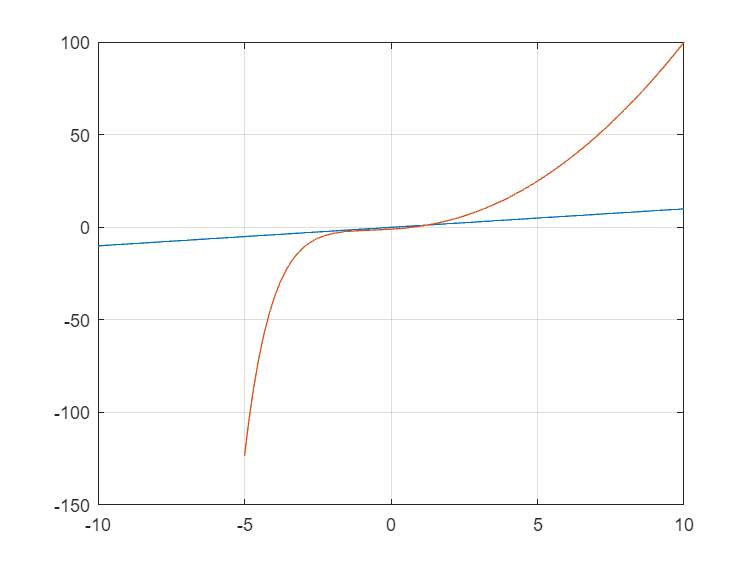


g4 = @(x) 1+exp(-x)./x;
dg4 = @(x) - exp(-x)/x - exp(-x)/x^2;
h = @(x) x.^2 -x-exp(-x);
xval = linspace(-10,10);
plot(xval,y(xval))


hold on
fplot(g1,[-5,10]) 
grid on
hold off

%x_r = fixed_p(g1,dg1,1)
x_r2 = fixed_p(g2,dg2,1)

x_r2 =    1.235309732154273


%x_r3 = fixed_p(g3,dg3,1)
x_r4 = fixed_p(g4,dg4,1)

x_r4 =    1.235369757253394


h(1.2353)

ans =     -8.143502539686986e-05


h(1.2354)

ans =      9.470827341662158e-05


6.

h = @(x)sin(x).*cos(2*x)

h = function_handle with value:
    @(x)sin(x).*cos(2*x)


dif_h=@(x) cos(2*x)*cos(x) - 2*sin(2*x)*sin(x)

dif_h = function_handle with value:
    @(x)cos(2*x)*cos(x)-2*sin(2*x)*sin(x)


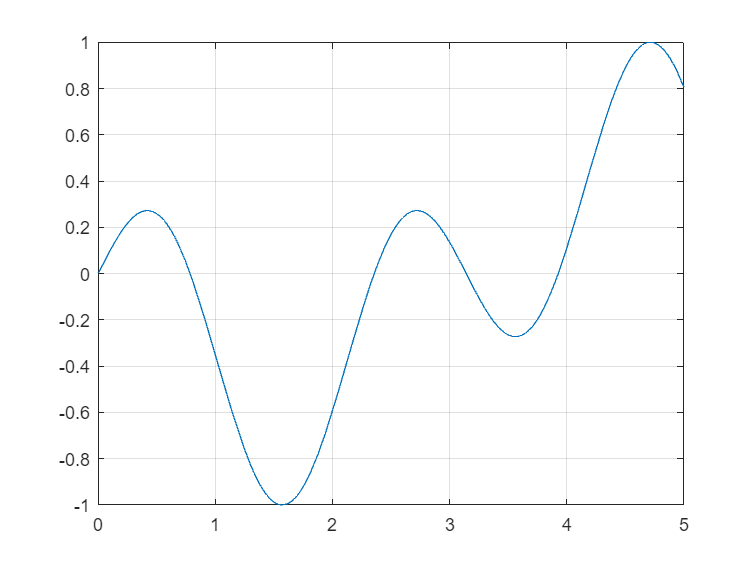


fplot(h,[0,5])
grid on

newton(h,dif_h,2,0.0001)

ans =    2.356174877171392



h(2.3562)

ans =      7.792001778713125e-06


7.

interval = linspace(-pi,pi);
root_val = [];
for i=1:length(interval)
    root_val(end+1)=newton(h,dif_h,interval(i),0.0001);
end
root_val

root_val =   -3.141592653589793  -3.141592647283657  -3.141588650947861  -3.141592653642793  -3.141593762959981  -2.356194323252024  -3.927015411750510   0.000000022765947  -2.356189807576111  -2.356194480032642  -2.356191429208495  -2.356194475680344  -2.356194096636526  -2.356192746404199  -2.356150784542593  -2.356194468069601  -2.356194442444126  -2.356194475932919  -2.356172045822195  -2.356190862781564  -2.356194373423753  -2.356194447060216  -3.141592653270859  -3.141538001357520  -0.785398186888851  14.922562754970093   0.785398210974136  -0.000000003814273  -3.141592824859005  -0.785404876872406  -0.785438541321489  -0.785398326773525  -0.785423809878410  -0.785398200949456  -0.785398202476297  -0.785490020598545  -0.785411825835789  -0.785458974629125  -0.785413393865466  -0.785398450518620  -0.785419576697081  -0.785398210376212  -5.497745955719930  10.210176178813390   0.785449555489703  -0.000000000025391   0.000000008524805  -0.000035471395112  -0.000000264593191  -0.0000

h(0)

ans =      0


h(-2.3562)

ans =     -7.792001778713125e-06


h(14.9226)

ans =      4.934789436026169e-05


h(-5.4977)

ans =     -1.232506570769152e-04


h(-10.2101)

ans =      1.076476332135809e-04


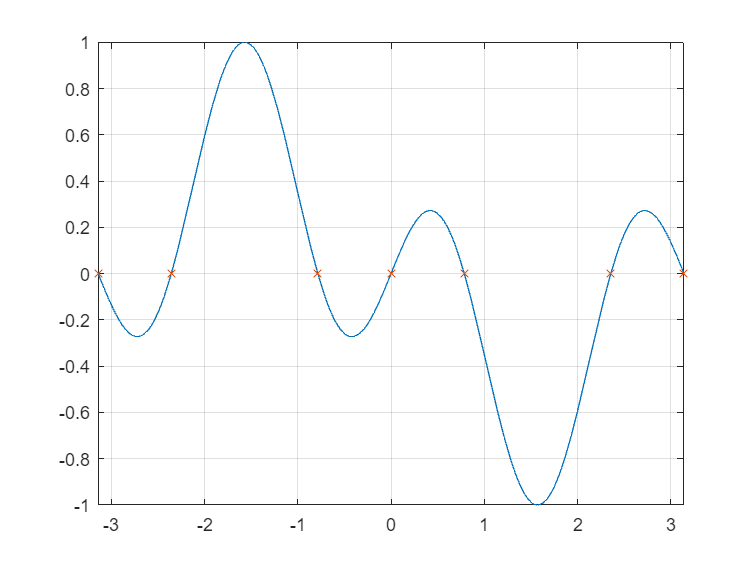

fplot(h,[-pi,pi])
grid on
hold on
plot(root_val,h(root_val),'x')
%plot(root1,r(root1),'or','MarkerFaceColor','r','MarkerSize',8)
ylim([-1,1])
xlim([-pi,pi])
hold off

8 

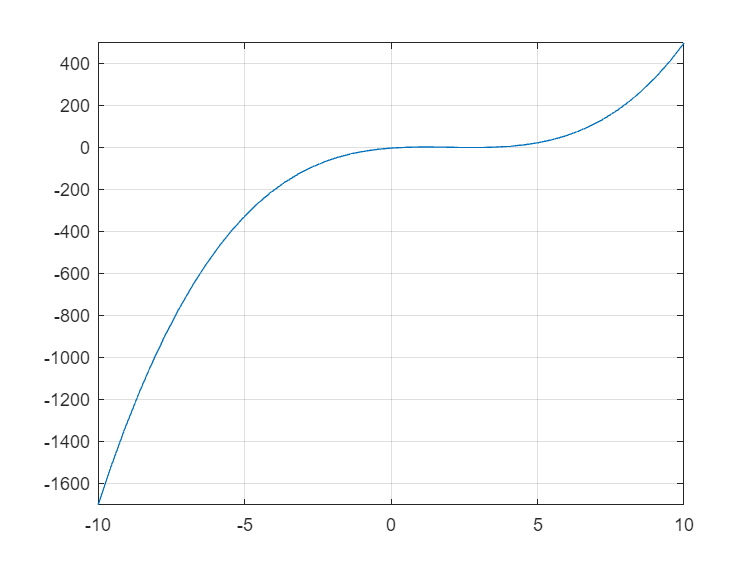

w = @(x) x.^3-6*x.^2+10*x-4;
fplot(w,[-10,10])
grid on

bracket=incsearch_stepsize(w,-5,5,1)

number of brackets:
     4



bracket =      0     1
     1     2
     2     3
     3     4


size_b=size(bracket);

bisect(w,0,1,0.0001)

ans =    0.585784912109375


bisect(w,1,2,0.0001)

ans =      2


bisect(w,2,3,0.0001)

ans =      2


bisect(w,3,4,0.0001)

ans =    3.414306640625000


9

v_func = @(h) (4*acos((2-h)./2)-(2-h).*sqrt(2*2*h-h.^2)).*5-8

v_func = function_handle with value:
    @(h)(4*acos((2-h)./2)-(2-h).*sqrt(2*2*h-h.^2)).*5-8


dv = @(h) 10/(1 - (h/2 - 1)^2)^(1/2) + 5*(- h^2 + 4*h)^(1/2) - (5*(2*h - 4)*(h - 2))/(2*(- h^2 + 4*h)^(1/2))

dv = function_handle with value:
    @(h)10/(1-(h/2-1)^2)^(1/2)+5*(-h^2+4*h)^(1/2)-(5*(2*h-4)*(h-2))/(2*(-h^2+4*h)^(1/2))


h=linspace(1,10)

h =    1.000000000000000   1.090909090909091   1.181818181818182   1.272727272727273   1.363636363636364   1.454545454545455   1.545454545454545   1.636363636363636   1.727272727272727   1.818181818181818   1.909090909090909   2.000000000000000   2.090909090909091   2.181818181818182   2.272727272727272   2.363636363636363   2.454545454545455   2.545454545454545   2.636363636363637   2.727272727272728   2.818181818181818   2.909090909090909   3.000000000000000   3.090909090909091   3.181818181818182   3.272727272727273   3.363636363636364   3.454545454545455   3.545454545454545   3.636363636363636   3.727272727272727   3.818181818181818   3.909090909090909   4.000000000000000   4.090909090909091   4.181818181818182   4.272727272727273   4.363636363636363   4.454545454545455   4.545454545454545   4.636363636363637   4.727272727272727   4.818181818181818   4.909090909090909   5.000000000000000   5.090909090909091   5.181818181818182   5.272727272727272   5.363636363636363   5.45454545454

v_func(h)

ans = 1.0e+02 *

  0.042836969860876 + 0.000000000000000i  0.058812030373029 + 0.000000000000000i  0.075209181789915 + 0.000000000000000i  0.091977123750652 + 0.000000000000000i  0.109067898956212 + 0.000000000000000i  0.126436227251261 + 0.000000000000000i  0.144038972473149 + 0.000000000000000i  0.161834704650011 + 0.000000000000000i  0.179783331315820 + 0.000000000000000i  0.197845778924879 + 0.000000000000000i  0.215983710075648 + 0.000000000000000i  0.234159265358979 + 0.000000000000000i  0.252334820642311 + 0.000000000000000i  0.270472751793079 + 0.000000000000000i  0.288535199402138 + 0.000000000000000i  0.306483826067948 + 0.000000000000000i  0.324279558244809 + 0.000000000000000i  0.341882303466698 + 0.000000000000000i  0.359250631761747 + 0.000000000000000i  0.376341406967306 + 0.000000000000000i  0.393109348928044 + 0.000000000000000i  0.409506500344930 + 0.000000000000000i  0.425481560857083 + 0.000000000000000i  0.440979033156283 + 0.000000000000000i  0.455938096723593 + 0

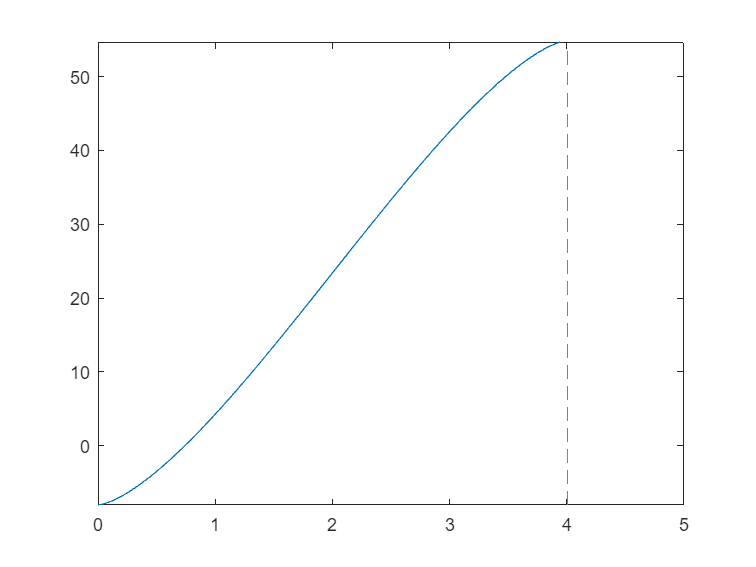


fplot(v_func,[0,5])

root_v = incsearch_stepsize(v_func,0,5,1)

number of brackets:
     1



root_v =      0     1


f_root = fzero(v_func,root_v)

f_root =    0.740015218055941


n_root = newt(v_func,dv,1,0.0001)

d =    0.247319360804445


d =    0.012624262417534


d =      4.115827971817865e-05


n_root =    0.740015218498303


10

h11=@(x) cos(x.^2./2)+cos(2*x);
dh= @(x) -2*sin(2*x) - x.*sin(x.^2/2);
ddh = @(x) - 4*cos(2*x) - sin(x^2/2) - x^2*cos(x^2/2);
fplot(h11,[-5,5])
grid on
hold on
fplot(dh,[-5,5])
interval_h = -5:0.001:5

interval_h =    -5.0000   -4.9990   -4.9980   -4.9970   -4.9960   -4.9950   -4.9940   -4.9930   -4.9920   -4.9910   -4.9900   -4.9890   -4.9880   -4.9870   -4.9860   -4.9850   -4.9840   -4.9830   -4.9820   -4.9810   -4.9800   -4.9790   -4.9780   -4.9770   -4.9760   -4.9750   -4.9740   -4.9730   -4.9720   -4.9710   -4.9700   -4.9690   -4.9680   -4.9670   -4.9660   -4.9650   -4.9640   -4.9630   -4.9620   -4.9610   -4.9600   -4.9590   -4.9580   -4.9570   -4.9560   -4.9550   -4.9540   -4.9530   -4.9520   -4.9510


root_dh_interval = incsearch_stepsize_num10(dh,-5,5,0.001) 

number of brackets:
     8



root_dh_interval =    -4.4030   -4.4020
   -3.4480   -3.4470
   -2.0870   -2.0860
   -0.0010         0
         0    0.0010
    2.0860    2.0870
    3.4470    3.4480
    4.4020    4.4030


rootdh_val=[];
real_r = [];
size_dh=size(root_dh_interval);

for i=1:size_dh(1)*size_dh(2)
    rootdh_val(end+1)=root_dh_interval(i);
end
rootdh_val

rootdh_val =    -4.4030   -3.4480   -2.0870   -0.0010         0    2.0860    3.4470    4.4020   -4.4020   -3.4470   -2.0860         0    0.0010    2.0870    3.4480    4.4030


for i = 1:length(rootdh_val)-1
    real_r(end+1) =newt(dh,ddh,rootdh_val(i),0.0001);
end

d = 3.4479e-04

d = 1.3954e-08

d = 3.0201e-04

d = 6.0581e-08

d = 7.7360e-04

d = 3.3611e-07

d = 0.0010

d = 1.0833e-09

d = 0

d = 2.2609e-04

d = 2.8690e-08

d = 6.9825e-04

d = 3.2519e-07

d = 6.5517e-04

d = 4.7788e-08

d = 6.5517e-04

d = 4.7788e-08

d = 6.9825e-04

d = 3.2519e-07

d = 2.2609e-04

d = 2.8690e-08

d = 0

d = 0.0010

d = 1.0833e-09

d = 7.7360e-04

d = 3.3611e-07

d = 3.0201e-04

d = 6.0581e-08


real_r

real_r =    -4.4027   -3.4477   -2.0862         0         0    2.0862    3.4477    4.4027   -4.4027   -3.4477   -2.0862         0         0    2.0862    3.4477


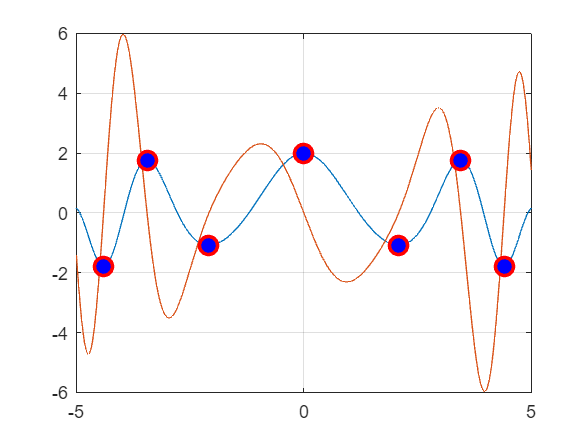

for i = 1:length(real_r)
    %plot(real_r(i),h11(real_r(i)),'x')
    plot(real_r(i),h11(real_r(i)), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'MarkerFaceColor', 'b');
end
hold off

Function

function [x0,n]=fixed_p(func,dif_func,xi)
while 1
    if dif_func(xi) > 1
        error('diff larger than 1')
    end
    x2=func(xi);
    error_val = abs(x2-xi);
    xi=x2;
    if error_val < 0.0001
        break
    end
end
x0 = x2;
end

function output = y(x)
    output = x;
end


function o=newton(func,diff_func,xi,tol)
while 1
    iteration = 0;
    x1=xi-(func(xi)/diff_func(xi));
    if abs(x1-xi)<tol
        break
    end
    xi=x1;
    iteration = iteration+1;
end

n = iteration;
o=xi;
end
